# Development of Innovation Form of State Space Models

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India    

## Introduction 

In this lesson we will learn how to obtain discrete linear state space models with output error structure, i.e. 

$\begin{array}{l}
\chi \left(k+1\right)=\Phi \chi \left(k\right)+\Gamma u\left(k\right)\\
y\left(k\right)=C\;\chi \left(k\right)+\varepsilon \left(k\right)
\end{array}$    --------(1)

using experimental data by treating elements of matrices $\Phi ,\Gamma ,C$ in equation(1) as unknowns. Here, $\chi \in R^n$ represents state vector, $u\in R^m$ represents manipulated inputs, $y\in R^r$ represents the vector of measured outputs, and $\varepsilon \in R^r$ represents output error, which is a combined error signal that comprises of measurement noise and approximation errors. In this lesson, we study how to develop black-box observers or the innovation form of state space models from experimental data. These models are are represented as follows 

$\begin{array}{l}
\chi \left(k+1\right)=\Phi \chi \left(k\right)+\Gamma u\left(k\right)+L\;e\left(k\right)\\
y\left(k\right)=C\;\chi \left(k\right)+e\left(k\right)
\end{array}$    --------(2)

where 

$e\left(k\right)=y\left(k\right)-C\;\chi \left(k\right)$   ------(3) 

$e\in R^r$ represents the innovation signal. In other words, we identify the observer gain matrix directly from the experimental data. Like linear perturbation models, these models are local and their range of applicability is limited to the operating range covered by the experimental data set used to estimate the model parameters. Nevertheless, the time required for development of these models is significantly less than the time required for developing a mechanistic dynamic model.  

**Learning Objectives:**

- To understand how to identify various forms of stationary Kalman filters from experimental data.

## From Stationary Kalman Filter to Black-Box Observer 

### Review of Stationary Kalman Filter 

To derive motivation for these class of models, we again go back to the stationary Kalman filter that we developed in Lesson 5 of Module 6 starting from a linearized mechanistic model. Recall that we started with 

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+w\left(k\right)$  -------(4)

$y\left(k\right)=\textrm{Cx}\left(k\right)+v\left(k\right)$ ------(5)

under the following simplifying assumptions: 

-  $\left\lbrace w\left(k\right)\right\rbrace$*is a zero mean Gaussian white noise sequence with known covariance *$\textrm{Cov}\left\lbrack w\left(k\right)\right\rbrack =Q$

- $\left\lbrace v\left(k\right)\right\rbrace$* is a Gaussian white noise with zero mean with known covariance *$\textrm{Cov}\left\lbrack v\left(k\right)\right\rbrack =R$

- $x\left(0\right)$* is a Gaussian random variable with *$\hat{\;x} \left(0\right)=E\left\lbrack x\left(0\right)\right\rbrack$ and $P\left(0\right)=\textrm{Cov}\left\lbrack x\left(0\right)\right\rbrack$

Under these assumptions, we derived a stationary Kalman predictor of the form 

$\hat{x} \left(k+1\right)=\Phi \hat{x} \left(k\right)+\Gamma u\left(k\right)+L_{\infty } e\left(k\right)$  ------(6)

$e\left(k\right)=y\left(k\right)-C\hat{x} \left(k\right)$ ------(7)

where the stationary observer gain matrix $L_{\infty } \;\textrm{and}$$\textrm{Cov}\left\lbrack \varepsilon \left(k\right)\right\rbrack =\textrm{Cov}\left\lbrack x\left(k\right)-\;\hat{x} \left(k\right)\right\rbrack =P_{\infty }$, are computed by solving the Alagebraic Riccati Equations (ARE)   

$P_{\infty } =\Phi P_{\infty } \Phi^T -L_{\infty } CP_{\infty } \Phi^T +Q$  ------(8)

$L_{\infty } =\Phi P_{\infty } {C^T \left\lbrack CP_{\infty } C^T +R\right\rbrack }^{-1}$  ------(9)

Note that 

$e\left(k\right)=y\left(k\right)-C\hat{x} \left(k\right)=C\varepsilon \left(k\right)+v\left(k\right)$  ------(10)

and, by subtracting eq. (6) from eq. (4) and rearranging, we can express the estimation error dynamics as follows  

$\varepsilon \left(k+1\right)=\left(\Phi -L_{\infty } \;C\right)\varepsilon \left(k\right)+w\left(k\right)-L_{\infty } v\left(k\right)$ ------(11)

where $\varepsilon \left(k\right)$ is a zero mean Gaussian random vector with covariance $P\left(0\right)$. Now, recursively using eq. (11)., it is easy to show that $\varepsilon \left(k\right)=\sum_{j=1}^k \Phi_{\textrm{CL}}^j \;\varepsilon \left(0\right)+\Phi_{\textrm{CL}}^{j-1} \left(w\left(k-j\right)-L_{\infty } v\left(k-j\right)\right)$  ------(12)

where $\Phi_{\textrm{CL}} =\left(\Phi -L_{\infty } \;C\right)$. From eq. (12), it is clear that $\varepsilon \left(k\right)$ is a weighted sum of Gaussian random vectors (RV). From the properties of Gaussian RVs, it follows that $\varepsilon \left(k\right)$ is also a zero mean Gaussian RV. Now, from eq. (10), it follows that 

$E\left\lbrack e\left(k\right)\right\rbrack =E\left\lbrack C\varepsilon \left(k\right)+v\left(k\right)\right\rbrack =\bar{0}$  ------(13) 

$E\left\lbrack e\left(k\right){e\left(k\right)}^T \right\rbrack =CP_{\infty } C^T +R$  ------(14)

i.e. $e\left(k\right)$ is a zero mean Gaussian RV as it is sum of two Gaussian RVs. Moreover, it can be shown that $e\left(k\right)$ is a white noise sequence, i.e. $E\left\lbrack e\left(k\right){e\left(k-j\right)}^T \right\rbrack =E\left\lbrack e\left(k\right){e\left(k+j\right)}^T \right\rbrack =\left\lbrack 0\right\rbrack$  for any $j\not= 0$. 

### Innovation form of Grey-Box Observer 

Thus, the stationary filter motivates a state space model of the form 

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+L\;e\left(k\right)$  ------(15)

$y\left(k\right)=C\;x\left(k\right)+e\left(k\right)$ ------(16)

which is driven by manipulated inputs and innovation sequence $\left\lbrace e\left(k\right)\right\rbrace$, which is a zero mean Gaussian white noise sequence. Note that the model description is complete when specify covariance of $e\left(k\right)$.  In the previous lesson, we estimated $\left(\Phi ,\Gamma \right)$  from experimental perturbation data. Here, we propose to estimate matrix $L$ in addition to $\left(\Phi ,\Gamma \right)$ from the experimental data using the ***prediction error method***. 

As an illustration, let us again consider the quadruple tank system with matrices 

$\Phi =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & \alpha_2  & 0\\
0 & \alpha_3  & 0 & \alpha_4 \\
0 & 0 & \alpha_5  & 0\\
0 & 0 & 0 & \alpha_6 
\end{array}\right\rbrack \;\;\textrm{and}\;\;\;\Gamma =\left\lbrack \begin{array}{cc}
\beta_1  & \beta_2 \\
\beta_3  & \beta_4 \\
0 & \beta_5 \\
\beta_6  & 0
\end{array}\right\rbrack$ -------(17)

In addition, we parameterize 

$L=\left\lbrack \begin{array}{cc}
\gamma_1  & \gamma_5 \\
\gamma_2  & \gamma_6 \\
\gamma_3  & \gamma_7 \\
\gamma_4  & \gamma_8 
\end{array}\right\rbrack$ ------(18)

and define parameter vector 

$\Theta ={\left\lbrack \begin{array}{ccccccccc}
\alpha_1  & \ldotp \ldotp \ldotp  & \alpha_6  & \beta_1  & \ldotp \ldotp \ldotp  & \beta_6  & \gamma_1  & \ldotp \ldotp \ldotp  & \gamma_8 
\end{array}\right\rbrack }^T$  --------(19)

the grey-box model can be expressed as follows

 $x\left(k+1\right)=\Phi \left(\Theta \right)x\left(k\right)+\Gamma \left(\Theta \right)u\left(k\right)+L\left(\Theta \right)\;e\left(k\right)$  ------(20)

For the purpose of model parameter estimation, let us rearrange equation (20) as follows 

 $x\left(k+1\right)=\left(\Phi \left(\Theta \right)-L\left(\Theta \right)\;C\right)x\left(k\right)+\Gamma \left(\Theta \right)u\left(k\right)+L\left(\Theta \right)\;y\left(k\right)$  ------(21)

Given set of manipulated inputs $U_N =\left\lbrace u\left(0\right),u\left(1\right),\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp u\left(N-1\right)\right\rbrace$, guess for $\Theta$ and initial state $\hat{x} \left(0\right)$, we can generate state sequence by recursively using difference equation,


$$\begin{array}{l}
\hat{y} \left(0\right)=C\hat{x} \left(0\right)\\
\hat{x} \left(1\right)=\left(\Phi \left(\Theta \right)-L\left(\Theta \right)\;C\right)\hat{x} \left(0\right)+\Gamma \left(\Theta \right)u\left(0\right)+L\left(\Theta \right)\;y\left(0\right)\\
\hat{y} \left(1\right)=C\hat{x} \left(1\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Downarrow \\
\hat{x} \left(2\right)=\left(\Phi \left(\Theta \right)-L\left(\Theta \right)\;C\right)\hat{x} \left(1\right)+\Gamma \left(\Theta \right)u\left(1\right)+L\left(\Theta \right)\;y\left(1\right)\\
\hat{y} \left(2\right)=C\hat{x} \left(2\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Downarrow \\
\hat{x} \left(3\right)=\left(\Phi \left(\Theta \right)-L\left(\Theta \right)\;C\right)\hat{x} \left(2\right)+\Gamma \left(\Theta \right)u\left(2\right)+L\left(\Theta \right)\;y\left(2\right)\\
\hat{y} \left(3\right)=C\hat{x} \left(3\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Downarrow \\
\ldotp \ldotp \ldotp \ldotp \ldotp =\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp 
\end{array}$$


Define prediction error, $\varepsilon \left(k\right)=y\left(k\right)-\hat{y} \left(k\right)$, estimates of $\Theta$ and initial state $\hat{x} \left(0\right)$ can be obtained  by solving optimization problem 

$\begin{array}{l}
\left(\hat{\Theta} ,\hat{x} \left(0\right)\right)=\min_{\Theta ,\hat{x} \left(0\right)} \;\;\sum_{k=0}^N {e\left(k\right)}^T W\;e\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;s\textrm{ubject}\;\textrm{to}\\
\hat{x} \left(k+1\right)=\left(\Phi \left(\Theta \right)-L\left(\Theta \right)\;C\right)\hat{x} \left(k\right)+\Gamma \left(\Theta \right)u\left(k\right)+L\left(\Theta \right)\;y\left(k\right)\\
e\left(k\right)=y\left(k\right)-C\hat{x} \left(k\right)\\
\;\textrm{for}\;\;\;k=0,1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp N-1
\end{array}$     --------(22)

In this case, $W$ is chosen as $W={\left(\textrm{Cov}\left\lbrack e\left(k\right)\right\rbrack \right)}^{-1}$. This choice yields maximum likelihood estimates of the parameter set. However, the resulting nonlinear optimization problem is difficult to solve. 

### Innovation form of Black-Box Observer

We started with a linearized mechanistic model and derived innovation form of grey-box model. This model motivates a more general form of innovation form of state space discrete time model representation  

$\chi \left(k+1\right)=\tilde{\Phi} \;\chi \left(k\right)+\tilde{\Gamma} u\left(k\right)+\tilde{L} e\left(k\right)$  -----(23)

$y\left(k\right)=\tilde{C} \chi \left(k\right)+e\left(k\right)$  ------(24)

Here the transformed state $\chi \left(k\right)$ can be a mathematical construct which need not have any physical interpretation. Moreover, the dimension of the state vector can be different from dimension of$x\left(k\right)$. When they are equal, one can think of $\chi \left(k\right)$ as some revertible transformation of $x\left(k\right)$, i.e. $\chi \left(k\right)=\psi \;x\left(k\right)\;$where $\Psi$ is a square non-singular matrix. The problem of identifying parameters of black-box model (23)-(24) can be formulated in a analogous manner as follows 

$\begin{array}{l}
\left(\hat{\Theta} ,\hat{\chi} \left(0\right)\right)=\min_{\Theta ,\hat{x} \left(0\right)} \sum_{k=0}^N {e\left(k\right)}^T \textrm{We}\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;s\textrm{ubject}\;\textrm{to}\\
\hat{\chi} \left(k+1\right)=\left(\tilde{\Phi} \left(\Theta \right)-\tilde{L} \left(\Theta \right)\;\tilde{C} \left(\Theta \right)\right)\hat{\chi} \left(k\right)+\Gamma \left(\Theta \right)u\left(k\right)+\tilde{L} \left(\Theta \right)y\left(k\right)\\
e\left(k\right)=y\left(k\right)-C\left(\Theta \right)\hat{\chi} \left(k\right)\\
\;\textrm{for}\;\;\;k=0,1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp N-1
\end{array}$ ------(25)

Similar to the previous case, $W$ is chosen as $W={\left(\textrm{Cov}\left\lbrack e\left(k\right)\right\rbrack \right)}^{-1}$ for generating the maximum likelihood estimates. 

### **Residual Analysis as Test of Observer Adequacy**

 A common test for model adequacy is plotting of the correlations of the innovations obtained using the identified observer. Innovations of a grey-box or black-box stationary Kalman filter identified from experimental data should have the same characteristics as white noise (zero mean, uncorrelated sequence). A signature of a white noise sequence is that the auto-correlation of the residuals resembles the Dirac delta function (nonzero at lag zero, and zero at non-zero lags). Further the cross-correlation between the residual and the system inputs should be zero throughout.

## Black-Box and Grey-Box Model Identification for Quadruple Tank System 

We will show an example of this approach for identifying the grey-box state space matrices equation(2) for the Quadruple Tank System. Though we have introduced the grey-box models first and then discussed black-box models, we go in the reverse sequence while identifying the state space models. This is because the grey-box model identification function in the System Identification Toolbox requires a good initial guess of model parameters. To generate such a guess, we first identify of model of the form (22)-(23) and use the identified model matrices to provide good initial guesses for the grey-box observer parameters. 

### 4'th Order Black-Box Observer Development 

**Task 1:** **Select operating conditions and Load experimental perturbation data set**

Select operating point: **(1) Minimum Phase Operation (2) Non-minimum phase operation. **This will load the parameters specific to the operating point. 

clear all
close all

operating_pt=2; 

Set_Graphics_Parameters

if operating_pt==1
    load QTank_Expt_Data_MinPhase
else
    load QTank_Expt_Data_NonMinPhase
end 
   

**Task 2: Create** **data object for System Identification toolbox. **

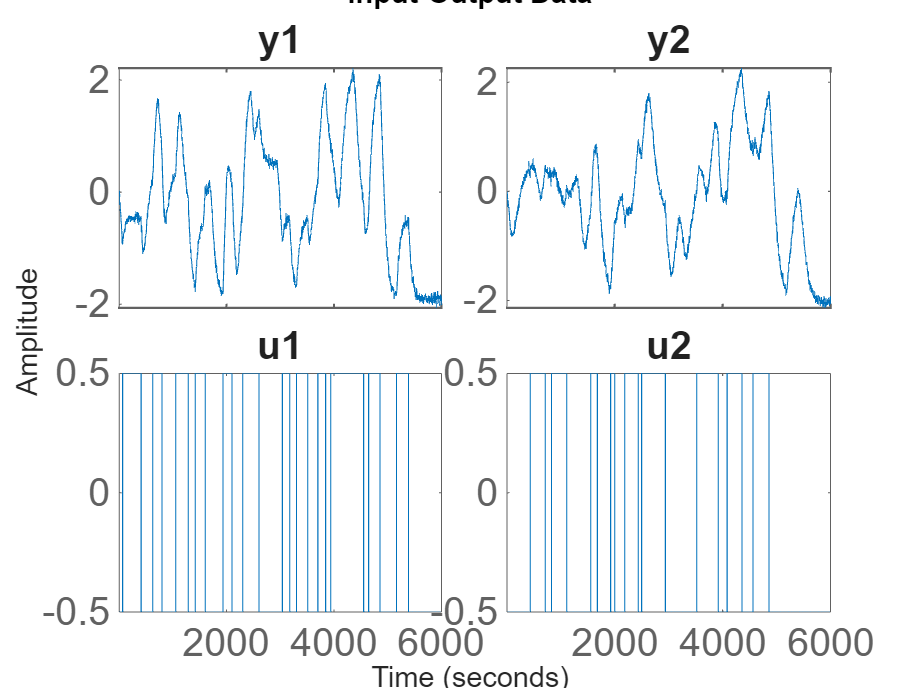

iddatayu=iddata(yk',uk',samp_T);
Est_Val_split =1500;% 1500% split into estimation and validation sets
iddatayuE = iddatayu(1:Est_Val_split); %Estimation Data
iddatayuV = iddatayu(Est_Val_split+1:end);  %Validation Data
idplot(iddatayuE)

**Task 3: Black-box Model identification ** 

We first identify a 4'th order black-box observer of the form 


$$\begin{array}{l}
x\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right)+K\;e\left(k\right)\\
y\left(k\right)=\textrm{Cx}\left(k\right)+\textrm{Du}\left(k\right)+e\left(k\right)
\end{array}$$


*where *$K$ represents the observer gain matrix and $e\left(k\right)$ represents the innovation, using the experimental data. 

%%%% Black-Box STATE SPACE Observer IDENTIFICATION  %%%%%%
% State space model of order 4 chosen based on prior knowledge 
n_st = 4 ; n_ip = 2 ; n_op = 2 ;  
BlackBox_mod_4 = pem(iddatayuE, n_st, 'DisturbanceModel', 'estimate')

BlackBox_mod_4 =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1         x2         x3         x4
   x1     0.9673  -0.005574   -0.01012   -0.01305
   x2    0.01419     0.9902    0.04639   0.002387
   x3    0.01185   -0.06013     0.8792   -0.01435
   x4    0.05794   -0.02034   -0.03564     0.9157
 
  B = 
              u1         u2
   x1  -0.002012  -0.001547
   x2   0.002598  -0.001445
   x3  -0.008799     0.0108
   x4   0.008727   0.007372
 
  C = 
            x1       x2       x3       x4
   y1   -30.28    8.975   -1.659  -0.8644
   y2   -27.93   -11.79    1.555  -0.9634
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
  K = 
              y1         y2
   x1  -0.003707  -0.001806
   x2   0.003177  -0.003994
   x3    0.00694   0.005097
   x4    0.03228    0.01342
 
Sample time: 4 seconds

Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   D

% Find simulated outputs using the identified black-box model 
y_blackbox_dev = sim(BlackBox_mod_4, uk');
y_blackbox_4 = y_blackbox_dev + Ys';

% Save model matrices for later use in controller synthesis 
idmod.phy= BlackBox_mod_4.A;
idmod.gam = BlackBox_mod_4.B;
idmod.C = BlackBox_mod_4.C;
idmod.D = BlackBox_mod_4.D;
idmod.L_mat = BlackBox_mod_4.K; 

 if operating_pt==1
     save('QTank_MP_BlackBox_INV_SS_4.mat', 'idmod')
 else
     save('QTank_NMP_BlackBox_INV_SS_4.mat', 'idmod')
 end


#### **Carry out residual analysis to assess whiteness of innovations  **

 This residual analysis is done using the **MATLAB **command** resid.  **`resid(`[`data`](https://in.mathworks.com/help/ident/ref/resid.html#bu20lex-Data)`,`[`sys`](https://in.mathworks.com/help/ident/ref/resid.html#bu20lex-sys)`)` computes the 1-step-ahead prediction errors (residuals) for an identified model, `sys`, and plots the auto-correlation of the residuals and the residual-input cross-correlation using the data in `Data`: For time-domain data, `resid` plots the auto-correlation (AutoCorr) of the residuals and the cross-correlation (XCorr) of the residuals with the input signals. The correlations are generated for lags -25 to 25. To specify a different maximum lag value, use [`residOptions`](https://in.mathworks.com/help/ident/ref/residoptions.html). The 99% confidence region marking statistically insignificant correlations displays as a shaded region around the X-axis. 

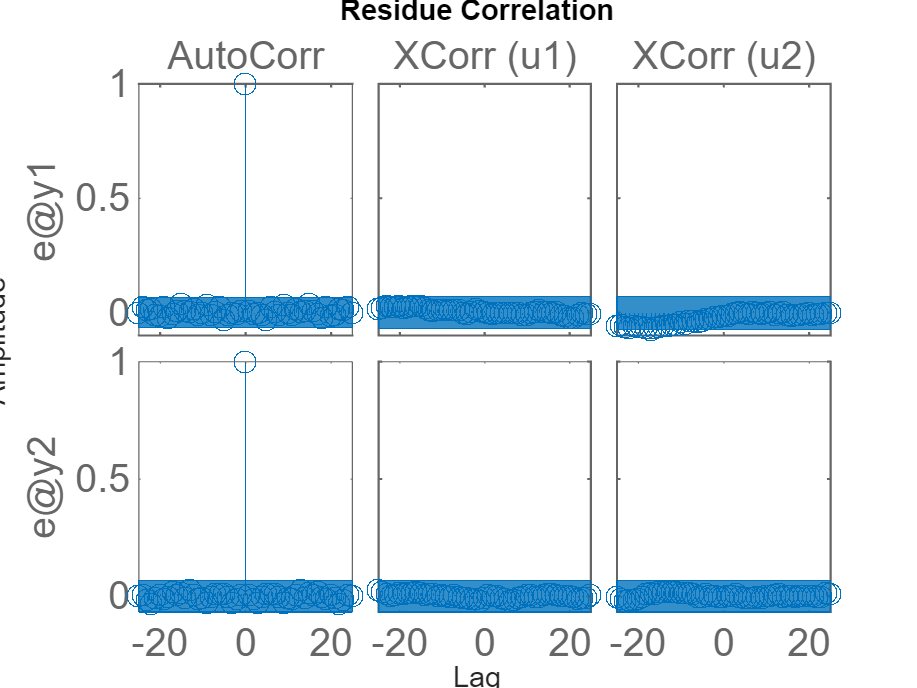

%%%%%%%%%% RESIDUAL ANALYSIS FOR VALIDATION SET %%%%%%%%%%%%
figure
resid(BlackBox_mod_4,iddatayuE,'corr')

Err_BlackBox_4 = resid(BlackBox_mod_4,iddatayuE) ;
Cov_Err_BlackBox_4 = cov(Err_BlackBox_4.OutputData)    % Estimate Innovation Covariance 

Cov_Err_BlackBox_4 =     0.0028    0.0000
    0.0000    0.0029


As can be observed from the residual plots, the innovation sequence generated by the identified model is a white noise sequence and there is no cross correlation of innovations with input signal for the minimum as well the non-minimum phase cases. 

### Grey-Box Observer Development 

**Grey-box Model - Initialization of model parameters**

Here we define the structure that we would like to impose on the linear gray-box model.  Since, we have already obtained a 4-state black-box model using the identification command ***pem***, let us use the corresponding elements as the initial guess for the parameters of $\Phi$:

alpha(1) = BlackBox_mod_4.A(1,1);
alpha(2) = BlackBox_mod_4.A(1,3);
alpha(3) = BlackBox_mod_4.A(2,2);
alpha(4) = BlackBox_mod_4.A(2,4);
alpha(5) = BlackBox_mod_4.A(3,3);
alpha(6) = BlackBox_mod_4.A(4,4);

The Initial guess for the unknown parameter beta are obtained from the state space model B matrix obtained using the ***pem*** command in the previous step.

beta(1) = BlackBox_mod_4.B(1,1);
beta(2) = BlackBox_mod_4.B(1,2);
beta(3) = BlackBox_mod_4.B(2,1);
beta(4) = BlackBox_mod_4.B(2,2);
beta(5) = BlackBox_mod_4.B(3,2);
beta(6) = BlackBox_mod_4.B(4,1);

Initial guess for observer gain matrix

gama = reshape( BlackBox_mod_4.K, [1, n_st*n_op] ) ;

These initial guesses are stored in **initial_par **

%The initial guess for the Gray-box model parameters 

initial_par = mat2cell([alpha beta gama]',20,1);

Now we create the **idgrey** model.  An [`idgrey` model ](https://in.mathworks.com/help/ident/ref/idgrey.html)represents a linear system as a continuous-time or discrete-time state-space model with identifiable (estimable) coefficients. Here **'myDiscreteGreyBoxModel_Observer**' is the function where the model structure is described.

Minit = idgrey('myDiscreteGreyBoxModel_Observer', initial_par, 'd', [], samp_T);

**Estimate the Grey-box model parameters**

We use the previously generated identification data *iddatayuE* and the system *Minit* as inputs to greyest. The estimated model is saved as GreyBox_model**.**

% Estimate the grey box model parameters
% It is important to use Simulation Focus here to ensure good steady state
% characteristics of the identified grey-box observer
mygreyboxoptions = greyestOptions('Focus','simulation','Display','off',...
    'SearchMethod','auto'); 
%Set max no. of iterations for termination in case of failure to converge 
mygreyboxoptions.SearchOptions.MaxIterations = 2000;  
GreyBox_model = greyest(iddatayuE, Minit,mygreyboxoptions)

GreyBox_model =
  Discrete-time linear grey-box model defined by "myDiscreteGreyBoxModel_Observer" function:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
            x1       x2       x3       x4
   x1   0.9398        0  -0.2539        0
   x2        0   0.9596        0   0.1145
   x3        0        0   0.9049        0
   x4        0        0        0   0.9391
 
  B = 
             u1        u2
   x1    0.1863  0.001064
   x2  0.007288     0.134
   x3         0   -0.1104
   x4    0.1133         0
 
  C = 
        x1   x2   x3   x4
   y1  0.5    0    0    0
   y2    0  0.5    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
  K = 
              y1         y2
   x1  -0.003707  -0.001806
   x2   0.003177  -0.003994
   x3    0.00694   0.005097
   x4    0.03228    0.01342
 
  Model parameters:
   Par1 = 
       0.9398
      -0.2539
       0.9596
       0.1145
       0.9049
       0.9391
       0.1863
     0.001064
     0.007288
        0.1

The output y_greybox of the grey box model GreyBox_model is obtained by simulating the model. 

% Find simulated outputs using the identified grey-box model 
y_greybox_dev = sim(GreyBox_model,uk');
y_greybox = y_greybox_dev + (Ys)'; 

**Save model matrices for future use.** 

 idmod.phy= GreyBox_model.A;
 idmod.gam = GreyBox_model.B;
 idmod.C = GreyBox_model.C;
 idmod.D = GreyBox_model.D;
 idmod.L_mat = GreyBox_model.K ;

 if operating_pt==1
     save('QTank_MP_GreyBox_INV_SS.mat', 'idmod')
 else
     save('QTank_NMP_GreyBox_INV_SS.mat', 'idmod')
 end

**Carry out residual analysis to assess whiteness of innovations  **

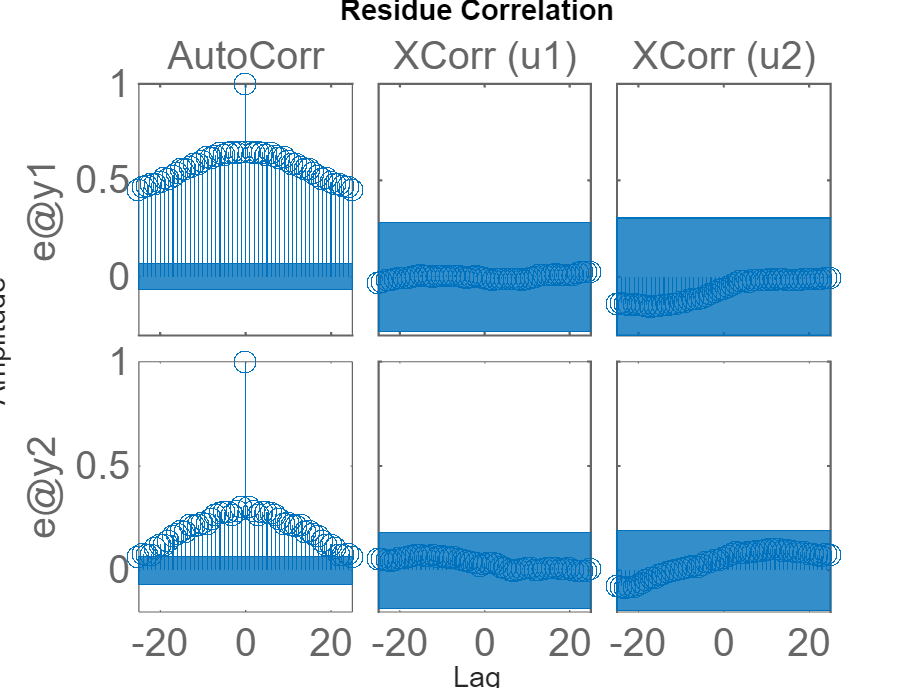

 %%%%%%%%%%%%% RESIDUAL ANALYSIS FOR VALIDATION SET %%%%%%%%%%%
figure
resid(GreyBox_model,iddatayuE,'corr')

Err_GreyBox = resid(GreyBox_model,iddatayuE) ;
Cov_Err_GreyBox = cov(Err_GreyBox.OutputData)

Cov_Err_GreyBox =     0.0047    0.0009
    0.0009    0.0038


** Minimum phase case:** As can be observed from the residual plots, the innovation sequence generated by the identified model is a white noise sequence and there is no cross correlation of innovations with input signal.** Non Minimum phase case:  T**he innovation sequence for the non-minimum phase case is ***auto-correlated and not a white noise sequence***. Thus, the observer identified in this case cannot be viewed as a stationary Kalman filter. 

### 6'th Order Black-Box Observer Development 

While developing the black-box model, we used the number of states equal to 4. In general, however, even the order of the state vector is unknown and a control engineer has to choose (guess) an appropriate order of the state vector. In such a situation, one may end up developing a state space model of order higher than the minimal order. Thus, let us also develop another black-box model when the state vector order is chosen as 6.  

**Develop a 6'th order black-box observer**


%%%% Black-Box Output Error STATE SPACE IDENTIFICATION  %%%%%%
% State space model of order 4 chosen based on prior knowledge 
n_st = 6 ; n_ip = 2 ; n_op = 2 ;  
BlackBox_mod_6 = pem(iddatayuE, n_st, 'DisturbanceModel', 'estimate')

BlackBox_mod_6 =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1      0.9734    0.006372  -0.0005391     0.01263   -0.005641     0.03388
   x2     0.02526       1.008    -0.05145    0.003917    -0.01308    0.007784
   x3   -0.005623     0.08151      0.9159    -0.01726     -0.1302    -0.05166
   x4    -0.08115     0.02325    -0.03704      0.9164      0.0216    -0.09487
   x5    -0.01151    0.008355      0.0714    -0.01265       0.596     -0.7659
   x6     0.01211     -0.0129     -0.0463     0.04667    -0.01647     0.04061
 
  B = 
              u1         u2
   x1   0.001826   0.001477
   x2  -0.002633   0.001056
   x3  -0.006521    0.01205
   x4   0.002179     0.0125
   x5  -0.003669    0.01559
   x6  -0.002183     0.0105
 
  C = 
             x1        x2        x3        x4        x5        x6
   y1     29.74    -10.26 


 % Find simulated outputs using the identified black-box model 
y_blackbox_dev_6 = sim(BlackBox_mod_6, uk');
y_blackbox_6 = y_blackbox_dev_6 + Ys';

% Save model matrices for later use in controller synthesis 
idmod.phy= BlackBox_mod_6.A;
idmod.gam = BlackBox_mod_6.B;
idmod.C = BlackBox_mod_6.C;
idmod.D = BlackBox_mod_6.D;
idmod.L_mat = BlackBox_mod_6.K; 

 if operating_pt==1
     save('QTank_MP_BlackBox_INV_SS_6.mat', 'idmod')
 else
     save('QTank_NMP_BlackBox_INV_SS_6.mat', 'idmod')
 end

**Carry out residual analysis to assess whiteness of innovations  **

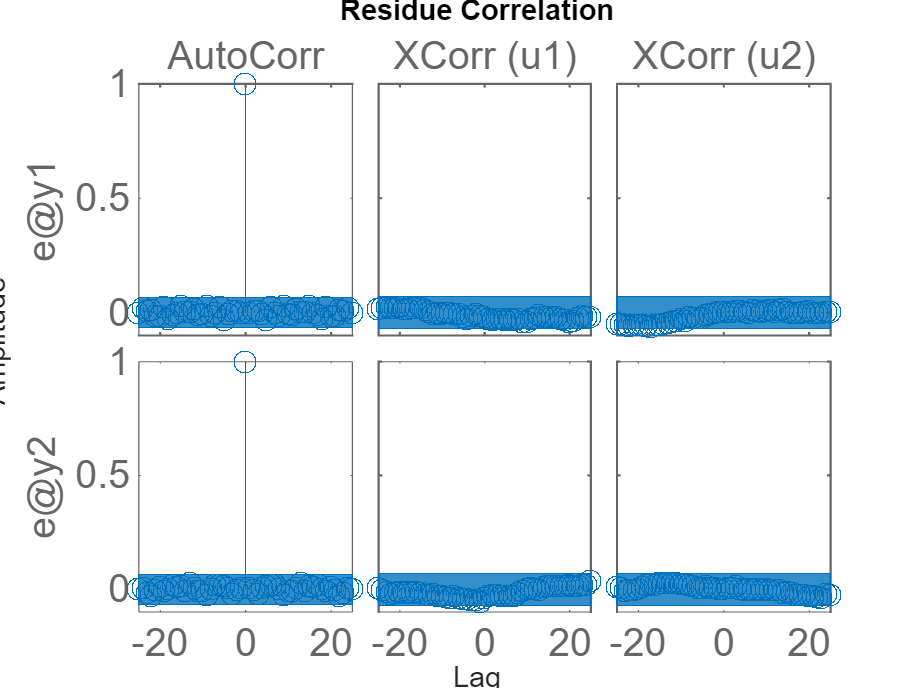

figure
resid(BlackBox_mod_6,iddatayuE,'corr')

Err_BlackBox_6 = resid(BlackBox_mod_6,iddatayuE) ;
Cov_Err_BlackBox_6 = cov(Err_BlackBox_6.OutputData)    % Estimate Innovation Covariance 

Cov_Err_BlackBox_6 =     0.0028    0.0000
    0.0000    0.0029


Note that the model residuals form a white noise sequence for the minimum as well the non-minimum phase cases. 

**Display simulated outputs **

Lets plot the model outputs and compare them with the measurements.

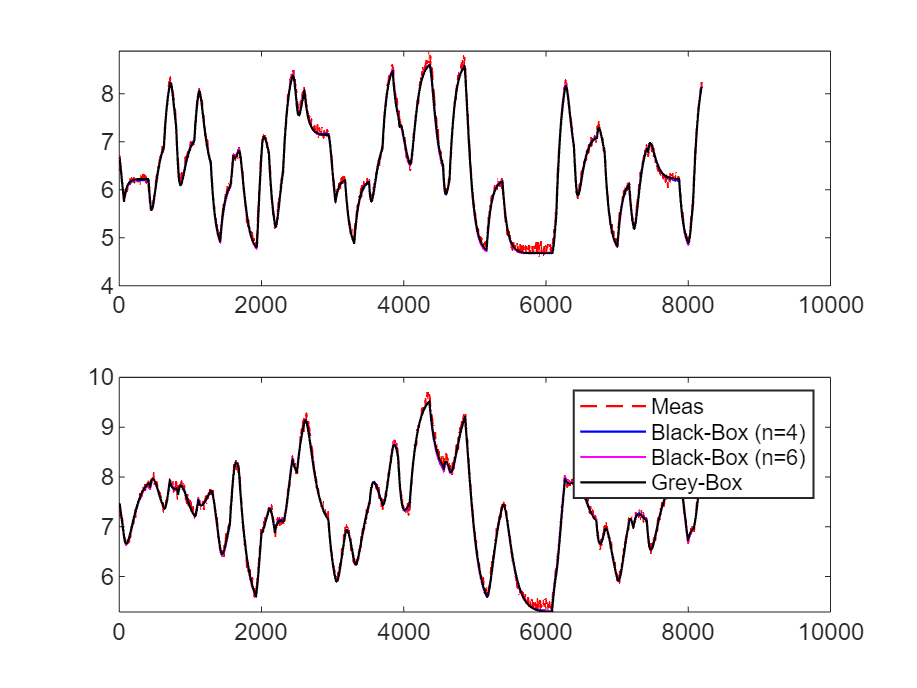

Yk = Ys + yk ;  % Create actual outputs from perturbation outputs

Set_Graphics_Parameters
 
figure(3)
subplot(2,1,1)
plot(kT,Yk(1,:)','r--') % raw measurements
hold on;
subplot(2,1,2)
plot(kT,Yk(2,:)','r--')
hold on;
figure(3)
% n4sid model output (this is black box)
subplot(2,1,1);hold on; plot(kT,y_blackbox_4(:,1),'b')
subplot(2,1,2);hold on; plot(kT,y_blackbox_4(:,2),'b'), 

%Grey box before fitting
figure(3)
subplot(2,1,1);hold on; plot(kT,y_blackbox_6(:,1),'m')
subplot(2,1,2);hold on; plot(kT,y_blackbox_6(:,2),'m'),

%Grey box after fitting
figure(3)
subplot(2,1,1);hold on; plot(kT,y_greybox(:,1),'k') %Fitted grey box
subplot(2,1,2);hold on; plot(kT,y_greybox(:,2),'k')
legend('Meas','Black-Box (n=4)','Black-Box (n=6)','Grey-Box')

## Model Validation

Lets compare performances of the above obtained linear discrete-time models (M_SS obtained using the subspace identification command ***pem*** and GreyBox_model  obtained using PEM on the grey-box model) for a validation data set **iddatayuV**.

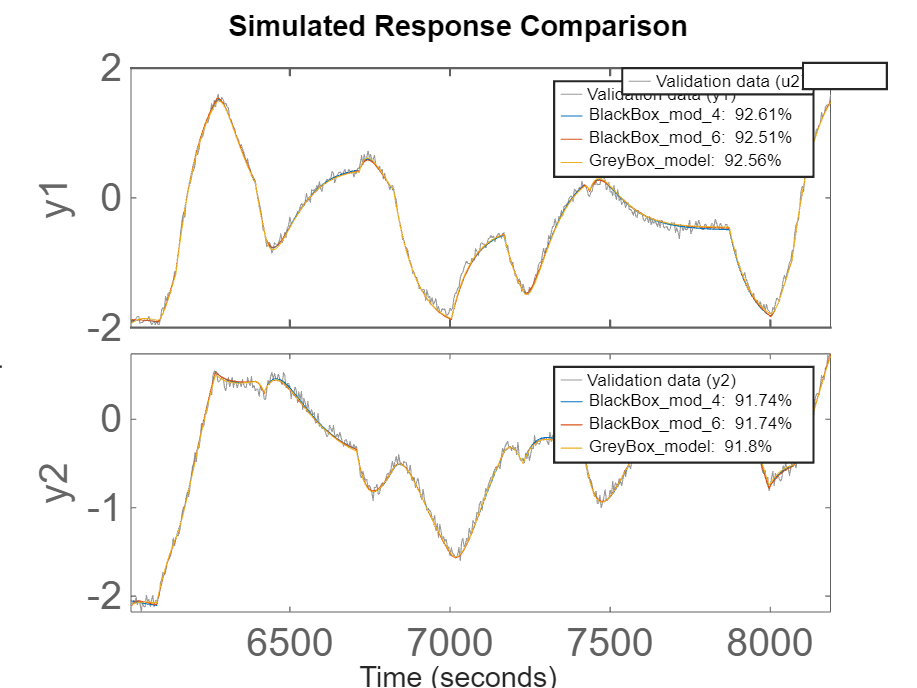

%%%%% COMPARE DIFFERENT MODELS ON VALIDATION SET 
%Lets compare performances on a validation set
figure(4)
compare(iddatayuV,BlackBox_mod_4, BlackBox_mod_6, GreyBox_model)
ax = findall(gcf,'type','axes');
for k = 1:length(ax)
    lgd = legend(ax(k));
    if ~isempty(lgd)
        lgd.FontSize = 8;
        lgd.ItemTokenSize = [10 10];
    end
end

 For the purpose of comparison, we load the linear perturbation model obtained using linearization of the mechanistic model. Let us now check the step responses of the linearized model and the grey box model

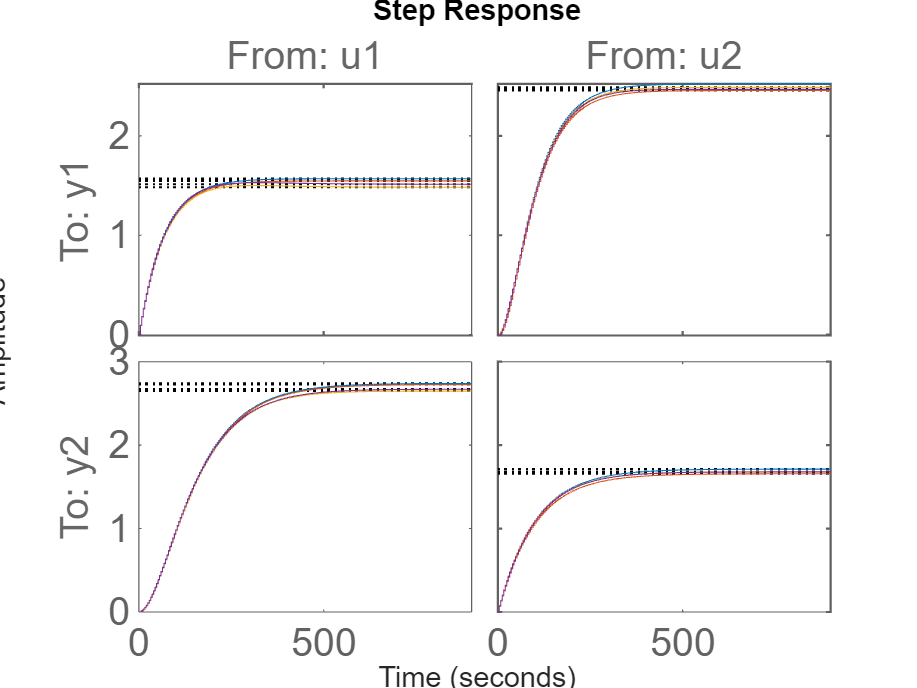

% Load linearized mechanistic model for the purpose of comparison

if operating_pt==1
    load QTank_MinPhase_Model
else
    load QTank_NonMinPhase_Model
end 

lin_mod=ss(QTank.phy, QTank.gama_u, QTank.C_mat, zeros(n_op,n_ip), samp_T);
step(lin_mod, GreyBox_model, BlackBox_mod_4, BlackBox_mod_6)

Let us examine how close are the identified grey-box model matrices to the linearized mechanistic model. 

delta_phy = QTank.phy - GreyBox_model.A 

delta_phy =     0.0006         0    0.3440         0
         0    0.0004         0   -0.0539
         0         0    0.0022         0
         0         0         0   -0.0010


delta_gam = QTank.gama_u - GreyBox_model.B

delta_gam =     0.0008    0.0133
   -0.0004    0.0030
         0    0.4060
    0.1035         0


The difference can be attributed to (a) non-uniqueness of the solution obtained using nonlinear optimization and (b) effects of process nonlinearity present in the input-output experimental data. The step responses of all three models, however, are almost identical. Thus, both the identified models can be used for controller synthesis. 

Finally, let us compare the steady state gain matrices the identified models with that of the linearized mechanistic model. 

MechLin_gain = QTank.C_mat * inv( eye(4) - QTank.phy) * QTank.gama_u

MechLin_gain =     1.5690    2.5232
    2.7408    1.7129


BlackBox_gain = BlackBox_mod_4.C * inv( eye(4) - BlackBox_mod_4.A) * BlackBox_mod_4.B

BlackBox_gain =     1.4829    2.4880
    2.6486    1.6798


BlackBox_gain = BlackBox_mod_6.C * inv( eye(6) - BlackBox_mod_6.A) * BlackBox_mod_6.B

BlackBox_gain =     1.5131    2.4675
    2.6709    1.6796


Greybox_gain = GreyBox_model.C * inv( eye(4) - GreyBox_model.A) * GreyBox_model.B

Greybox_gain =     1.5470    2.4564
    2.7266    1.6570


## Summary and Conclusions

In this lesson, we have learnt how to identify various forms of stationary Kalman filters from experimental data. The quadruple tanks simulation results reveal that the dynamic and the steady state characteristics of the identified observers is almost identical to the locally linearized mechanistic model. In addition to identifying the deterministic component of the model driven by the manipulated input sequence, the grey-box/black-box observers additionally construct a model for unmeasured stochastic disturbances in the state dynamics and the measurement noise. These observers can be further used for predictive controller synthesis.  

## References

-  HouWang : Z.-S. Hou and Z. Wang, "From model-based control to data-driven control: Survey, classification and perspective," Information Sciences, vol. 235, pp. 3--35, 2013

- Shumway, R. H., Stoffer, D. S. Time Series Analysis and Its Applications  

- Ljung, L., Glad, T., Modeling of Dynamic Systems, Prentice Hall, N. J., 1994.

- Ljung, L., System Identification: Theory for Users, Prentice Hall, 1987. 

- Soderstorm and Stoica, System Identification, 1989.

- Astrom, K. J., and B. Wittenmark, Computer Controlled Systems, Prentice Hall India (1994).

- Franklin, G. F., Powell, J. D., and M. L. Workman, Digital Control Systems, Addison Wesley, 1990.